# **primer punto **

## obtener la solucion de la ecuacion y obtener una respuesta temporal para (a>100>0) y otra para (0>b>5*a)

## la ecuacion es la siguiente de


syms y(t) a b
% las derivadas son 2
Dy=diff(y,t,1);
D2y=diff(y,t,2);

% las condiciones iniciales
Cond1=D2y(0)==a;
Cond2=y(0)==b;
Conds=[Cond1,Cond2];

%ecucacion diferencial
ode=D2y+3*Dy+2*y==2*t;


%la solucion sale
SOL=dsolve(ode,Conds);
pretty(SOL)

              / b   a   1 \           / 4 b   a     \   3
t - exp(-2 t) | - - - + - | + exp(-t) | --- - - + 2 | - -
              \ 3   3   2 /           \  3    3     /   2



clc,clear
syms s a b
A=s^2+3*s+2;
%descompongo la ecuacion en dos
t1=2/(s^2*A);
t2=(b*s+a+3*b)/(A);
y(s)=(t1+t2)

$$y(s) = \frac{a+3\,b+b\,s}{s^{2}+3\,s+2}+\frac{2}{s^{2}\,\left(s^{2}+3\,s+2\right)}$$

yt=ilaplace(y(s));
pretty(collect(simplify(yt)))

                                      /         1 \   3
t + exp(-t) (a + 2 b + 2) - exp(-2 t) | a + b + - | - -
                                      \         2 /   2



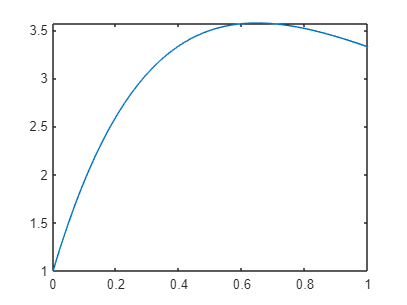

%Graficas
a=11;b=1;
fplot(subs(yt),[0 1])

$$ans = \frac{2}{s^{2}}$$

figure(2)
0>b>5*a;
fplot(subs(yt),[0 1])